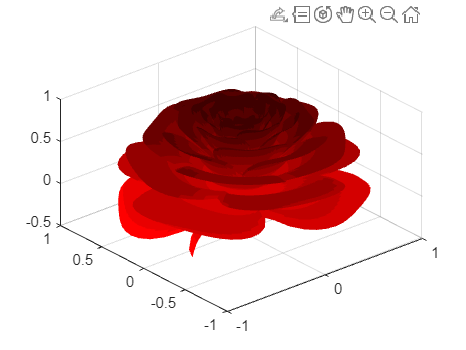

n = 800;
A = 1.995653;
B = 1.27689;
C = 8;
r=linspace(0,1,n);
theta=linspace(-2,20*pi,n);
[R,THETA]=ndgrid(r,theta);
% define the number of petals we want per cycle. Roses have 3 and a bit.
petalNum=3.6;
x = 1 - (1/2)*((5/4)*(1 - mod(petalNum*THETA, 2*pi)/pi).^2 - 1/4).^2;
phi = (pi/2)*exp(-THETA/(C*pi));
y = A*(R.^2).*(B*R - 1).^2.*sin(phi);
R2 = x.*(R.*sin(phi) + y.*cos(phi));
X=R2.*sin(THETA);
Y=R2.*cos(THETA);
Z=x.*(R.*cos(phi)-y.*sin(phi));
% % define a red map for our rose colouring
red_map=linspace(1,0.25,10)';
red_map(:,2)=0;
red_map(:,3)=0;
clf
surf(X,Y,Z,'LineStyle','none')
view([-40.50 42.00])
colormap(red_map)